a=1+mod(109,3);
N = 64;

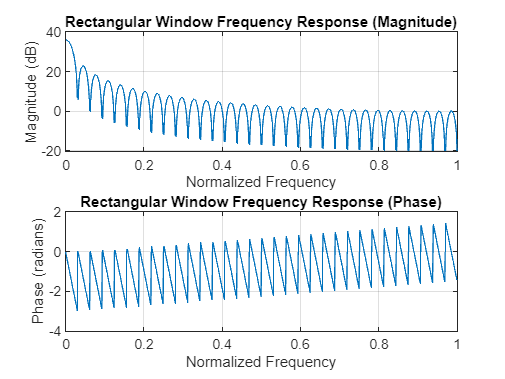

% Define the length of the window
N = 64;

% Create the rectangular window
rectangular_window = rectwin(N);

% Compute the frequency response
freq_response_rectangular = freqz(rectangular_window, 1, 1024);

% Plot the magnitude of the frequency response
subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_rectangular)));
title('Rectangular Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase of the frequency response
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_rectangular));
title('Rectangular Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

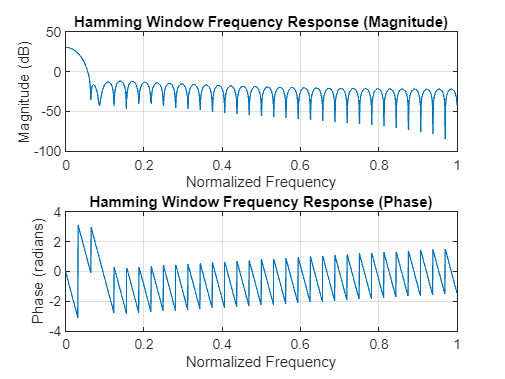

% Create the Hamming window
hamming_window = hamming(N);

% Compute the frequency response
freq_response_hamming = freqz(hamming_window, 1, 1024);

% Plot the magnitude of the frequency response
subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_hamming)));
title('Hamming Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase of the frequency response
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_hamming));
title('Hamming Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

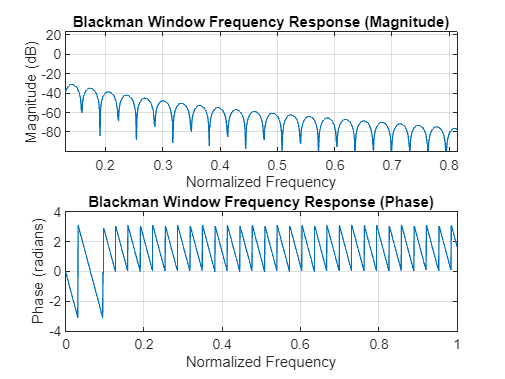

% Create the Blackman window
blackman_window = blackman(N);

% Compute the frequency response
freq_response_blackman = freqz(blackman_window, 1, 1024);

% Plot the magnitude of the frequency response
subplot(2, 1, 1);
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_blackman)));
title('Blackman Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase of the frequency response
subplot(2, 1, 2);
plot(linspace(0, 1, 1024), angle(freq_response_blackman));
title('Blackman Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

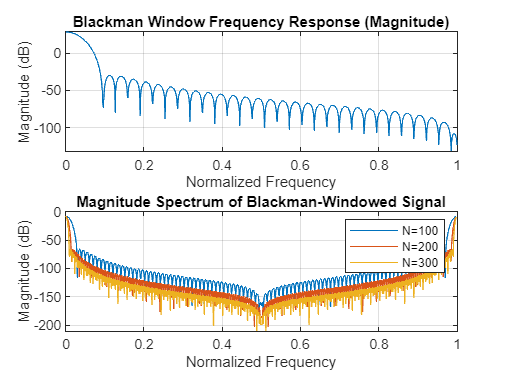

% Define the value of alpha
alpha = 2;

% Define the different lengths
N_values = [100,200,300];

% Number of points for the DFT
N_DFT = 1024;

% Create a frequency axis for the DFT
freq_axis = (0:N_DFT-1) / N_DFT;

% Loop through different lengths
for N = N_values
    % Generate the Blackman window
    blackman_window = blackman(N);
    
    % Generate a signal (e.g., a sine wave)
    t = 0:1/N:(N-1)/N;
    signal = 1; % Replace with your desired signal
    
    % Apply the Blackman window to the signal
    windowed_signal = signal .* (blackman_window');
    
    % Compute the DFT of the windowed signal
    dft = fft(windowed_signal, N_DFT);
    
    % Normalize the magnitude by the actual length
    normalized_magnitude = abs(dft) / N;
    
    % Plot the magnitude spectrum
    plot(freq_axis, 20*log10(normalized_magnitude));
    hold on;
end

% Label the plot and add a legend
title('Magnitude Spectrum of Blackman-Windowed Signal');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('N=100','N=200','N=300');

% Set grid and hold off
grid on;
hold off;

%as n increases frequency resolution increases

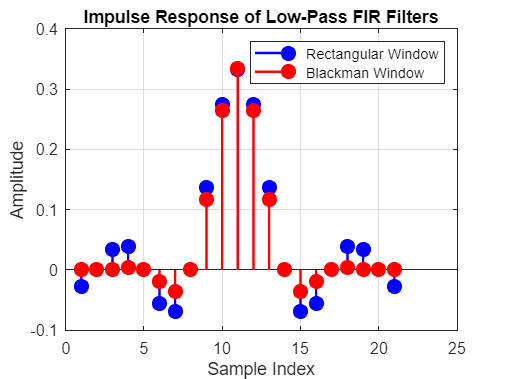

% Parameters
alpha = 2; % Blackman window
window_length = 21;
cutoff_frequency = pi / (alpha + 1);

% Design FIR filters with different windows
rectangular_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', rectwin(window_length));
blackman_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', blackman(window_length));

% Impulse responses on the same graph using different colors
figure;
stem(rectangular_filter, 'b', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
stem(blackman_filter, 'r', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;
title('Impulse Response of Low-Pass FIR Filters');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Rectangular Window', 'Blackman Window');
grid on;

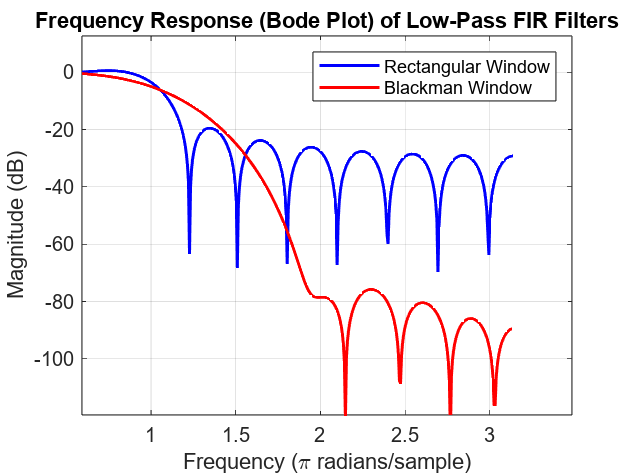


% Frequency responses on the same graph using different colors
[frequency_response_rect, freq_rect] = freqz(rectangular_filter, 1, 'half');
[frequency_response_blackman, freq_blackman] = freqz(blackman_filter, 1, 'half');

figure;
plot(freq_rect, 20*log10(abs(frequency_response_rect)), 'b', 'LineWidth', 1.5);
hold on;
plot(freq_blackman, 20*log10(abs(frequency_response_blackman)), 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Response (Bode Plot) of Low-Pass FIR Filters');
xlabel('Frequency (\pi radians/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'Blackman Window');
grid on;


% Comment on the filters
disp('The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.');

The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the Blackman window filter.


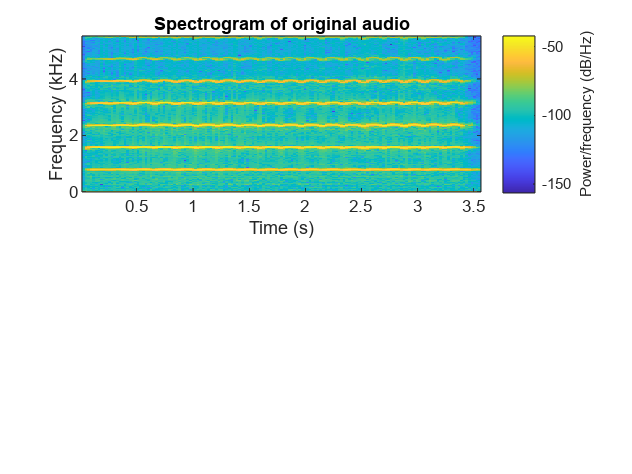

% Load the audio file
[y, fs] = audioread('instru2 (1).wav');

% Compute the DFT of the audio signal
N = length(y);
dft = fft(y, N);
% Compute the spectrogram of the original audio
figure;
subplot(2, 1, 1);
spectrogram(y, hamming(512), 256, 512, fs, 'yaxis');
title('Spectrogram of original audio');


% Compute the magnitude spectrum of the DFT
magnitude_spectrum = abs(dft);

% Calculate the fundamental frequency (excluding DC component)
[~, peak_index] = max(magnitude_spectrum(2:end));
fundamental_frequency = peak_index * fs / N

fundamental_frequency = 2.3691e+03

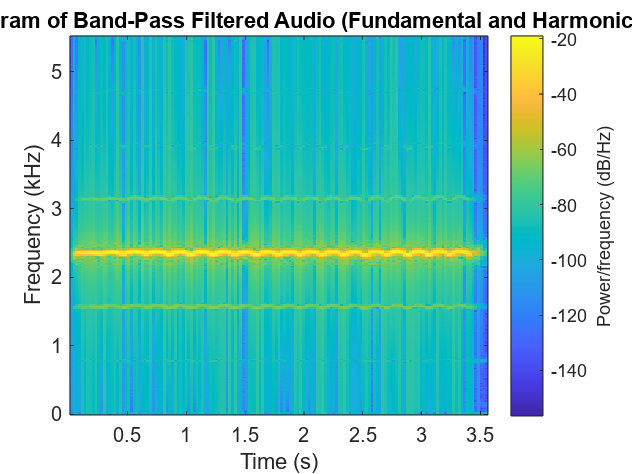


% Define the desired band-pass frequency range (in Hz)
low_cutoff = fundamental_frequency - 20; % Adjust as needed
high_cutoff = fundamental_frequency + 20; % Adjust as needed

% Normalize the cutoff frequencies to the Nyquist rate
nyquist_freq = fs / 2;
low_cutoff_normalized = low_cutoff / nyquist_freq;
high_cutoff_normalized = high_cutoff / nyquist_freq;

% Design a band-pass FIR filter using the Hamming window
filter_order = 63; % Adjust the filter order as needed
filter_coefficients = fir1(filter_order, [low_cutoff_normalized, high_cutoff_normalized], 'bandpass', hamming(filter_order + 1));

% Apply the FIR filter to the audio signal
filtered_audio = filter(filter_coefficients, 1, y);

% Normalize the filtered audio
filtered_audio = filtered_audio / max(abs(filtered_audio));

% Write the filtered audio to a new .wav file
audiowrite('filtered_instru_bandpass.wav', filtered_audio, fs);

% Play the filtered audio
sound(filtered_audio, fs);

% Compute and plot the spectrogram of the filtered audio
figure;
spectrogram(filtered_audio, hamming(512), 256, 512, fs, 'yaxis');
title('Spectrogram of Band-Pass Filtered Audio (Fundamental and Harmonics)');

sound(filtered_audio, fs)


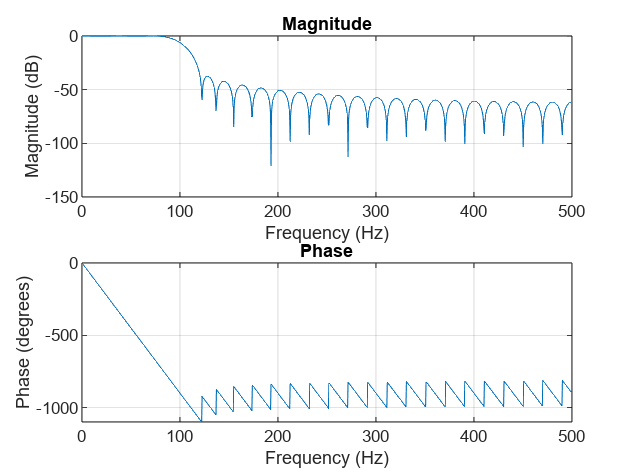

%4

% Time-domain windowing
% Generate a simple signal
Fs = 1000; % Sampling frequency
t = 0:1/Fs:1; % Time vector
f = 5; % Frequency of the signal
signal = sin(2 * pi * f * t);

% Apply a Hamming window to the signal
windowed_signal = signal .* hamming(length(signal));

% Plot the original and windowed signals
subplot(2, 1, 1);

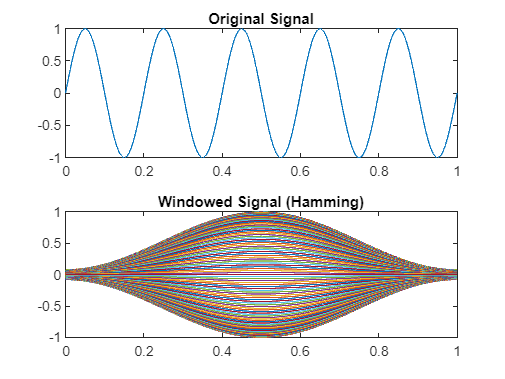

plot(t, signal);
title('Original Signal');
subplot(2, 1, 2);
plot(t, windowed_signal);
title('Windowed Signal (Hamming)');

% Design a low-pass FIR filter using the Kaiser window method
Fs = 1000; % Sampling frequency
cutoff_freq = 100; % Cutoff frequency in Hz
filter_order = 50; % Filter order
beta = 3; % Kaiser window shape parameter

% Design the filter
window = kaiser(filter_order + 1, beta);
filter_coefficients = fir1(filter_order, cutoff_freq / (Fs/2), 'low', window);

% Plot the filter's frequency response
freqz(filter_coefficients, 1, 1024, Fs);


% Apply the filter to a signal
filtered_signal = filter(filter_coefficients, 1, signal);
% Compute and plot the output of the filter
y = filter(b, 1, x); % Filter the signal
figure(3)
plot(y)
title('Output of the FIR filter')
